load experiment_readout.mat;

t = mat_pie_data(:, 1);
sensor_left = mat_pie_data(:, 2);
sensor_right = mat_pie_data(:, 3);
motor_left = mat_pie_data(:, 4);
motor_right = mat_pie_data(:, 5);

cutoff_hz = 4;
RC = 1/(cutoff_hz * 2 * pi);

sensor_left_filtered = lpf_data(t, sensor_left, RC);

tf_lpf = tf(1, [RC, 1]);
tspan_even = t(1) : mean(diff(t)) : t(end);

sensor_left_filtered = lsim(tf_lpf, sensor_left, tspan_even);
sensor_left_filtered(1) = sensor_left(1);

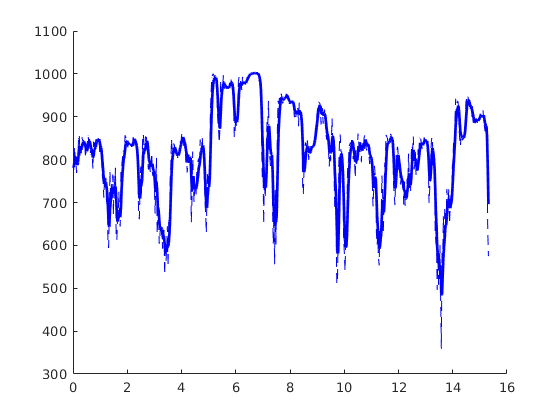

figure()
hold on
plot(t, sensor_left, 'b--');
plot(t, lpf_data(t, sensor_left, RC), 'b', 'linewidth', 2)

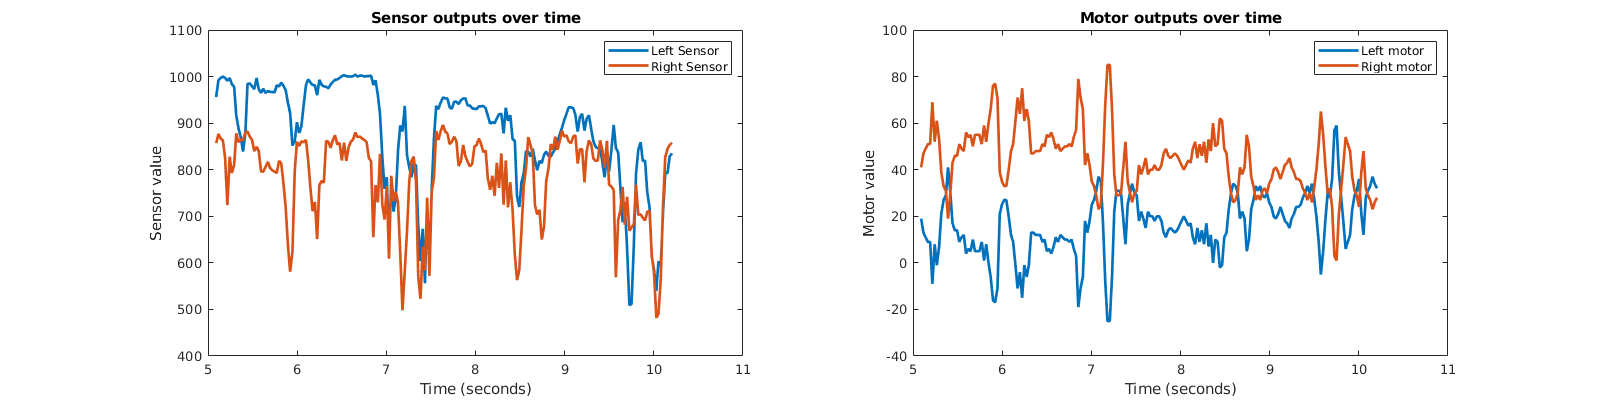

figure();
set(gcf, 'position', [0, 0, 1600, 400])
v_timespan = length(t) / 3 : length(t) * 2/3;
subplot(1, 2, 1)
plot(t(v_timespan), mat_pie_data(v_timespan, 2:3), 'linewidth', 2);
legend("Left Sensor", "Right Sensor");
title("Sensor outputs over time");
xlabel("Time (seconds)")
ylabel("Sensor value")

subplot(1, 2, 2)
plot(t(v_timespan), mat_pie_data(v_timespan, 4:5), 'linewidth', 2)
legend("Left motor", "Right motor");
title("Motor outputs over time");
xlabel("Time (seconds)")
ylabel("Motor value")

figure();
hold on

set(gcf, 'position', [0, 0, 1600, 400])
v_timespan = length(t) / 3 : length(t) * 2/3;

subplot(1, 2, 1)
hold on
plot(t(v_timespan), lpf_data(t(v_timespan), sensor_left(v_timespan), RC), 'linewidth', 2);

plot(t(v_timespan), lpf_data(t(v_timespan), sensor_right(v_timespan), RC), 'linewidth', 2);

title("Filtered sensor data for shortened time window")
legend("Left Sensor", "Right Sensor");

subplot(1, 2, 2)
hold on
plot(t(v_timespan), lpf_data(t(v_timespan), motor_left(v_timespan), RC), 'linewidth', 2);

plot(t(v_timespan), lpf_data(t(v_timespan), motor_right(v_timespan), RC), 'linewidth', 2);

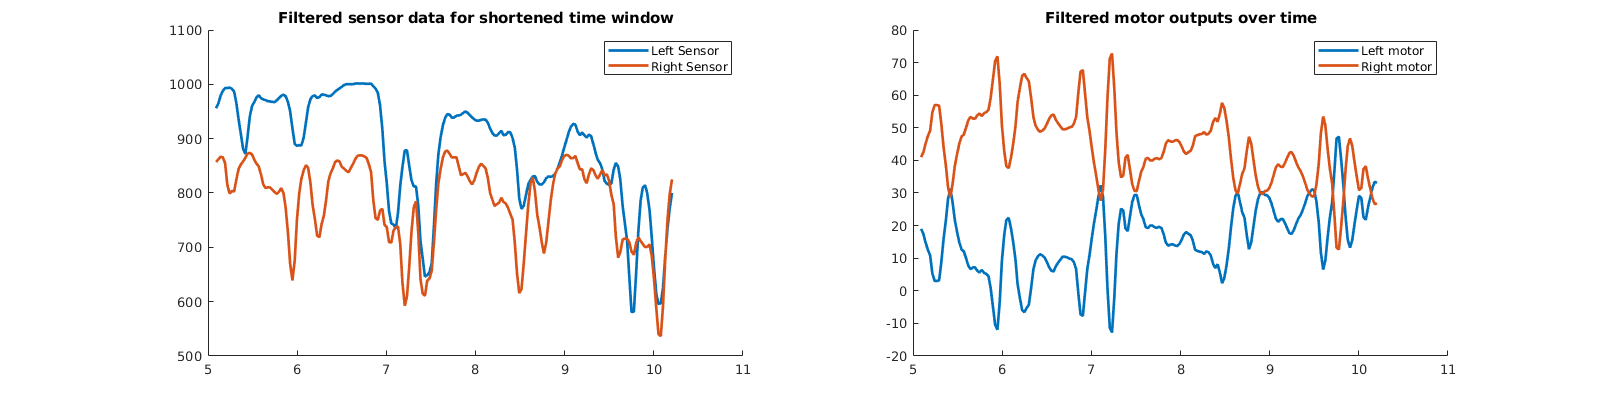

legend("Left motor", "Right motor");
title("Filtered motor outputs over time");i


%plot(t(v_timespan), sensor_left(v_timespan), 'b--');


function data_out = lpf_data(t, data, RC)
    tf_lpf = tf(1, [RC, 1]);
    tspan_even = t(1) : mean(diff(t)) : t(end);
    
    data_zero_centered = data - data(1);
    
    data_out = lsim(tf_lpf, data_zero_centered, tspan_even);
    data_out = data_out + data(1);
end